clc
clear all


cargar datos y convertir variables cualitativas en categóricas

data = readtable("finchData.csv");
data.Species = categorical(data.Species);
data.Year = categorical(data.Year)

data = 651×5 table
    Band    Species    BeakLength    BeakDepth    Year
    ____    _______    __________    _________    ____

      2     fortis         9.4            8       1975
      9     fortis         9.2          8.3       1975
     12     fortis         9.5          7.5       1975
     15     fortis         9.5            8       1975
    305     fortis        11.5          9.9       1975
    307     fortis        11.1          8.6       1975
    308     fortis         9.9          8.4       1975
    309     fortis        11.5          9.8       1975
    311     fortis        10.8          9.2       1975
    312     fortis        11.3            9       1975
    313     fortis        11.5          9.5       1975
    314     fortis        11.5          8.9       1975
    315     fortis         9.7          

Crea tablas separadas para las diferentes especies de aves (fortis y Scandens):

scandens = data(data.Species == "scandens",:);
fortis = data(data.Species == "fortis",:);

**ACTIVIDAD**

Cree un diagrama de dispersión de las medidas de longitud y profundidad del pico de un pinzón utilizando la función `scatter`. Utilice `data.BeakLength` como datos del eje *x*.

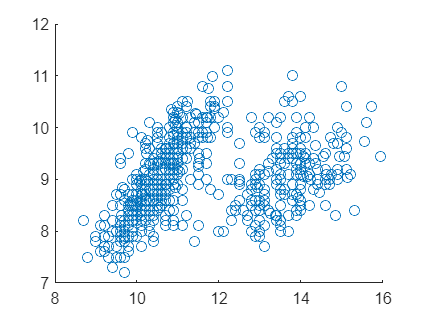

scatter(data.BeakLength,data.BeakDepth)

xlabel('longitud del pico (mm)')
ylabel('profundidad del pico (mm)')

**ACTIVIDAD**

Utilice `gscatter` para crear un diagrama de dispersión agrupado de las medidas de longitud y profundidad del pico, con la especie como variable de agrupación. Añada las etiquetas correspondientes a los ejes x e y.

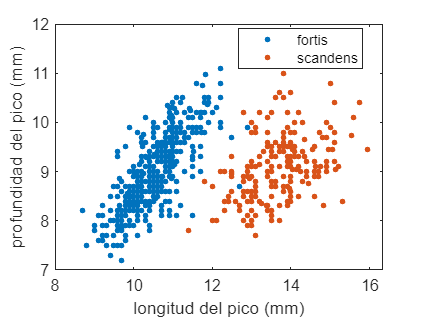

figure
gscatter(data.BeakLength,data.BeakDepth,data.Species)
xlabel('longitud del pico (mm)')
ylabel('profundidad del pico (mm)')

Puede especificar más de una variable de agrupación para un diagrama de dispersión agrupado, colocándolas entre llaves `{}`. Copie y pegue el siguiente código para ver un diagrama de dispersión agrupado tanto por la especie de pinzón como por el año en que se recogieron los datos.

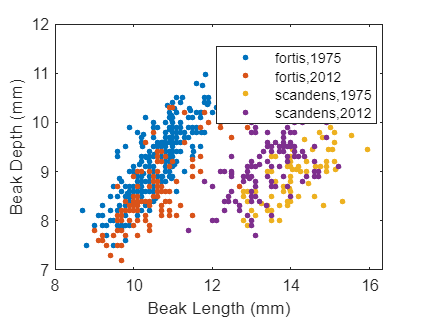

gscatter(data.BeakLength,data.BeakDepth,...
          {data.Species,data.Year})
xlabel("Beak Length (mm)")
ylabel("Beak Depth (mm)")